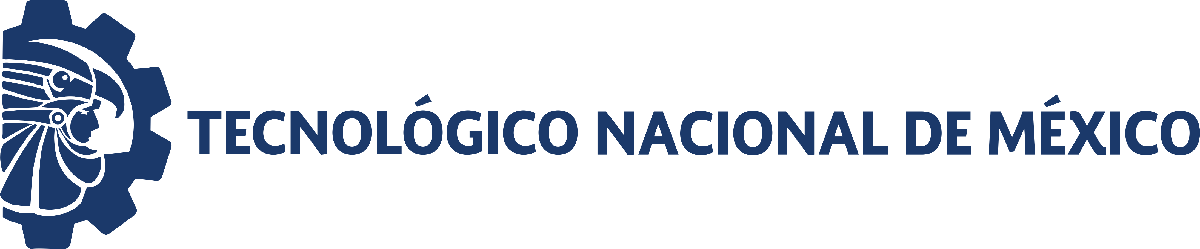                                 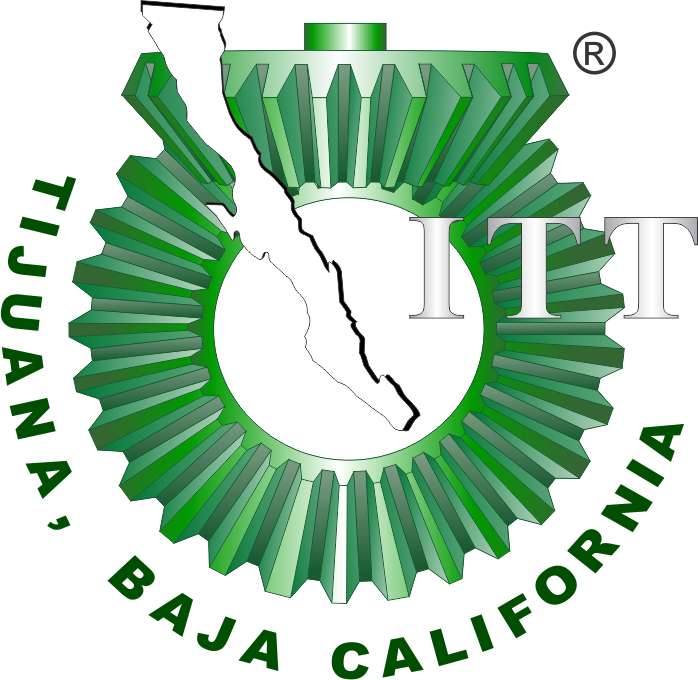

# Práctica: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

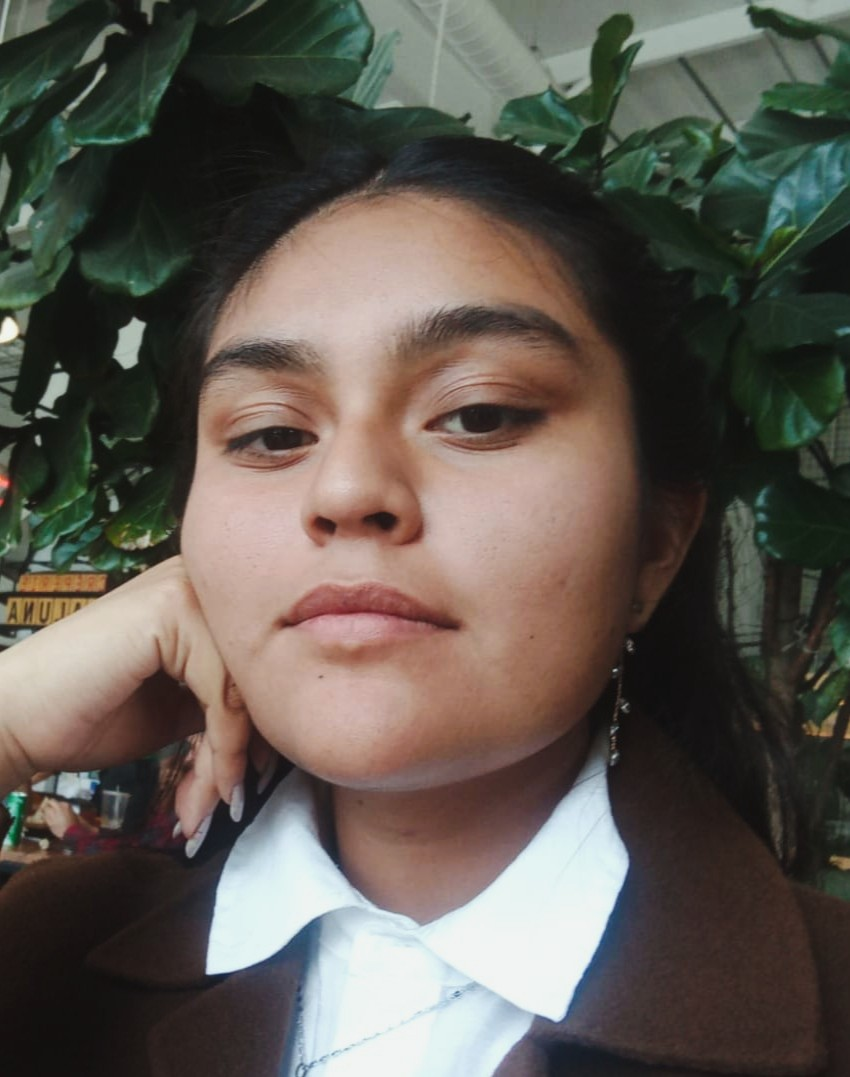

Nombre del alumno: **Bricia Idalia Arellano Salones**

Número de control: **22211746**

Correo institucional: **L22211746@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

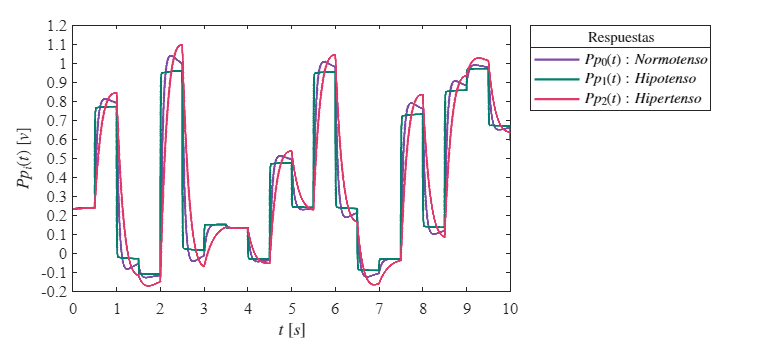

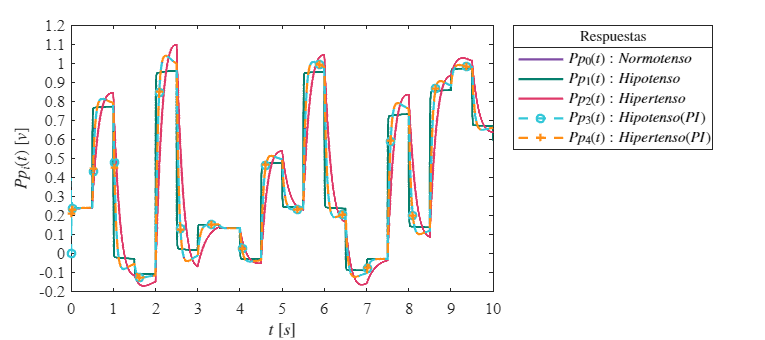

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime = tend; 
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('sistema/Ppa(t)', 'Minimum', '-0.2');
set_param('sistema/Ppa(t)', 'Maximum', '1');
set_param('sistema/Ppa(t)', 'Seed', '106');
set_param('sistema/Ppa(t)', 'SampleTime', '0.5');
x = sim(file, parameters);
writematrix(x.Ppa, 'signal.xlsx');
plotsignals(x.t, x.Pp0, x.Pp1, x.Pp2, x.Pp3, x.Pp4);

## Función: Respuesta a las señales

function plotsignals (t,Pp0,Pp1, Pp2,Pp3,Pp4)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [0.4980,    0.2980,    0.6471;
                0.0196,    0.4980,    0.4275;
                0.8745,    0.2235,    0.4118;
                0.2000,    0.7804,    0.8471;
                1.0000,    0.5529,    0.0784;
                0.4824,    0.1765,    0.2627];
    colororder(mycolors);
    p = plot(t, Pp0, t, Pp1, t, Pp2,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    L = legend('$Pp_{0}(t): Normotenso$','$Pp_{1}(t): Hipotenso$','$Pp_{2}(t): Hipertenso$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.2, 1.2]); yticks(-0.2:0.1:1.2);
    exportgraphics(gcf, 'Sistema Cardiovascular.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Sistema Cardiovascular.png', 'ContentType', 'vector')
set(figure(), 'Color', 'w');
        set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    colororder(mycolors);
     p1 = plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-', t, Pp3, '--o', t,...
        Pp4, '--+','LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    L1 = legend('$Pp_{0}(t): Normotenso$','$Pp_{1}(t): Hipotenso$','$Pp_{2}(t): Hipertenso$', ...
        '$Pp_{3}(t): Hipotenso (PI)$','$Pp_{4}(t): Hipertenso (PI)$');
    title(L1,'Respuestas', 'FontSize', 10);
    set(L1, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.2, 1.2]); yticks(-0.2:0.1:1.2);
    exportgraphics(gcf, 'Sistema Cardiovascular PIs.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Sistema Cardiovascular PIs.png', 'ContentType', 'vector')
end